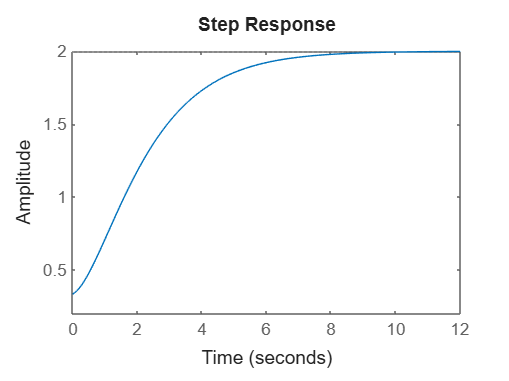

% Transfer function 
num = [1 2 4];
denom = [3 5 2];

sys = tf(num, denom);

step(sys); % Step response

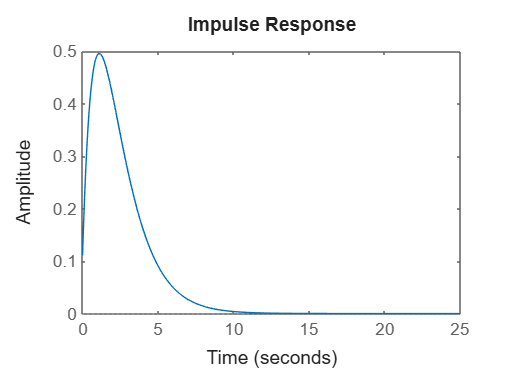

impulse(sys); % Impulse response

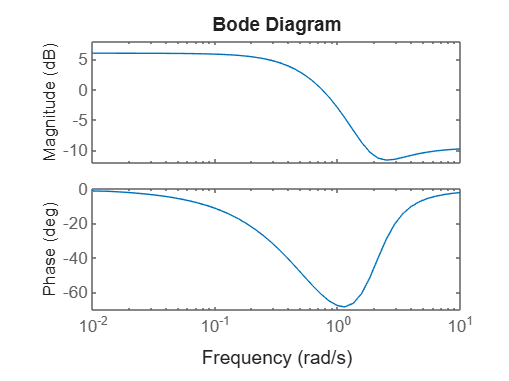

bode(sys);

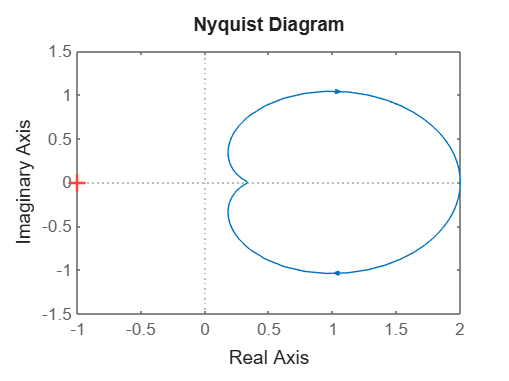

nyquist(sys);

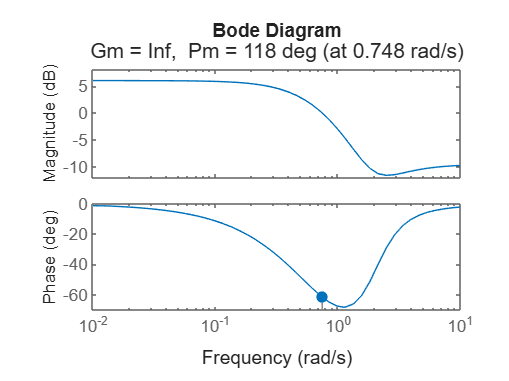

pole(sys);
zero(sys);
margin(sys);



num1 = [1 2];
denom1 = [3 5 2];
num2 = [6 9];
denom2 = [4 1 5];
sys1 =tf(num1, denom1);
sys2 = tf(num2, denom2);
closed_feedback = feedback(sys1, sys2);
disp(closed_feedback);

  tf with properties:

       Numerator: {[0 4 9 7 10]}
     Denominator: {[12 23 34 48 28]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1x1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1x1 struct]
           Notes: [0x1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1x1 struct]









% Define the numerator and denominator coefficients for the transfer function
num = [1 2 4];        % Numerator of the transfer function (coefficients of s^2 + 2s + 4)
denom = [3 5 2];      % Denominator of the transfer function (coefficients of s^2 + 5s + 2)

% Create the transfer function sys with the given numerator and denominator
sys = tf(num, denom);

% Plot the step response of the system
step(sys); % This shows how the system reacts to a step input, i.e., its time-domain behavior.

% Plot the impulse response of the system
impulse(sys); % This shows how the system responds to an impulse input, helping understand system dynamics.

% Plot the Bode plot of the system, which displays magnitude and phase against frequency
bode(sys); % Useful for analyzing the frequency response of the system, including stability and resonant behavior.

% Plot the Nyquist plot of the system
nyquist(sys); % The Nyquist plot helps analyze the stability of a control system and its frequency response.

% Find the poles of the transfer function sys
pole(sys); % Returns the poles of the transfer function, which indicate system stability and dynamic behavior.

% Find the zeros of the transfer function sys
zero(sys); % Returns the zeros of the transfer function, which represent the values of input that lead to zero output.

% Find the gain margins and phase margins of the system for stability analysis
margin(sys); % This function shows the stability margins, including gain margin and phase margin.

% Define two transfer functions sys1 and sys2 with different numerators and denominators
num1 = [1 2];        % Numerator of the first transfer function (coefficients of s + 2)
denom1 = [3 5 2];    % Denominator of the first transfer function (coefficients of s^2 + 5s + 2)
num2 = [6 9];        % Numerator of the second transfer function (coefficients of 6s + 9)
denom2 = [4 1 5];    % Denominator of the second transfer function (coefficients of s^2 + s + 5)

% Create two transfer functions sys1 and sys2
sys1 = tf(num1, denom1);   % Transfer function sys1 with given numerator and denominator
sys2 = tf(num2, denom2);   % Transfer function sys2 with given numerator and denominator

% Create a closed-loop transfer function with feedback
closed_feedback = feedback(sys1, sys2); % This function calculates the closed-loop transfer function
                                        % when sys2 is the feedback to sys1.

% Display the closed-loop transfer function
disp(closed_feedback); % Display the transfer function of the closed-loop system (feedback system).


